matrix = [];

for i = 1:29
    %sick = EEG_samples(i).data.sick;
    non_sick = EEG_samples(i).data.non_sick;
    matrix = cat(1, matrix, non_sick);
    %matrix = cat(1, matrix, sick);
end

EEG_data = matrix(:,4:19,:);

% Find epochs with signal values greater than 100 or less than -100
outside_range = (EEG_data > 100) | (EEG_data < -100);
epochs_to_plot = find(any(any(outside_range, 3), 2));

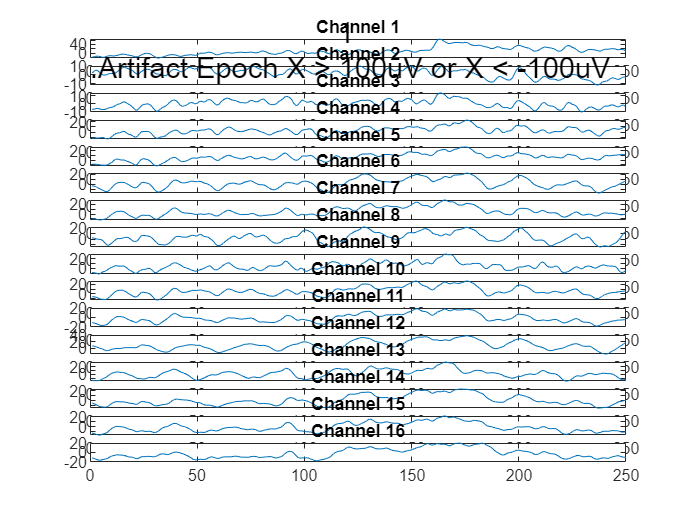

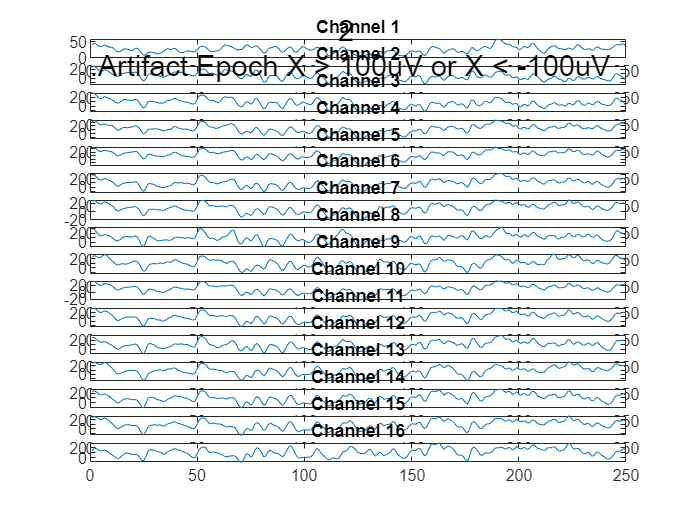

% Plot the epochs with signal values greater than 100 or less than -100
for i = 1:numel(epochs_to_plot)
    epoch_idx = epochs_to_plot(i);
    figure;
    for ch = 1:size(EEG_data, 2)
        subplot(size(EEG_data, 2), 1, ch);
        plot(squeeze(EEG_data(epoch_idx, ch, :)));
        title(['Channel ', num2str(ch)]);
    end
    sgtitle([num2str(i), " .Artifact Epoch X > 100uV or X < -100uV"]);
end

channels = zeros(16,1);
for i = 1:size(epochs_to_plot,1)
    epoch = squeeze(EEG_data(epochs_to_plot(i),:,:));
    artifact_range = (epoch > 100) | (epoch < -100);
    channels_artifact = find(any(artifact_range,2));

    for j = 1:size(channels_artifact)
        channels(channels_artifact(j)) = channels(channels_artifact(j)) + 1;
    end
end